# Batch Test Runner

%% ------------------- PATH SETUP -----------------------------
% If you are reading this, I failed at hiding this. Hello!
try
    repoDir = fileparts(matlab.desktop.editor.getActiveFilename());
catch
    repoDir = fileparts(mfilename("fullpath"));
end

functionsDir        = fullfile(repoDir, "functions");
imageSampleSetsDir  = fullfile(repoDir, "imageSampleSets");
sampleDataFolder    = fullfile(imageSampleSetsDir, "sample_test_02", "images");   % 10 clean + 10 defect

addpath(genpath(functionsDir));

netFileName    = "1785125303951_trainedInspectAI.mat";
netMatFile     = fullfile(repoDir, netFileName);
netReleaseURL  = "https://github.com/AndyV0/Defect-Detection-Pipeline---Wood-Grain/releases/download/1.0/1785125303951_trainedInspectAI.mat";

if exist(fullfile(functionsDir, "inspectPart.m"), "file") ~= 2
    error("batchTestRunner:missingFunction", ...
        "inspectPart.m not found in %s.\nMake sure inspectPart.m is in functions/, and scratchDetection.m / brushDetection.m are in functions/classicalDetection/ (or wherever they live under functions/ -- genpath adds all nested subfolders automatically).", functionsDir);
end
%%

## Introduction

This live script contains all information and visuals we have made for BTAD's 2nd dataset. This includes the methodology, results of batch testing, analysis of defect detection system, and the many, many problems we encountered along the way. The second dataset consists of images of wood grain-texture. These images are the focal point of this project. Here is an example of a clean image of wood for this dataset:

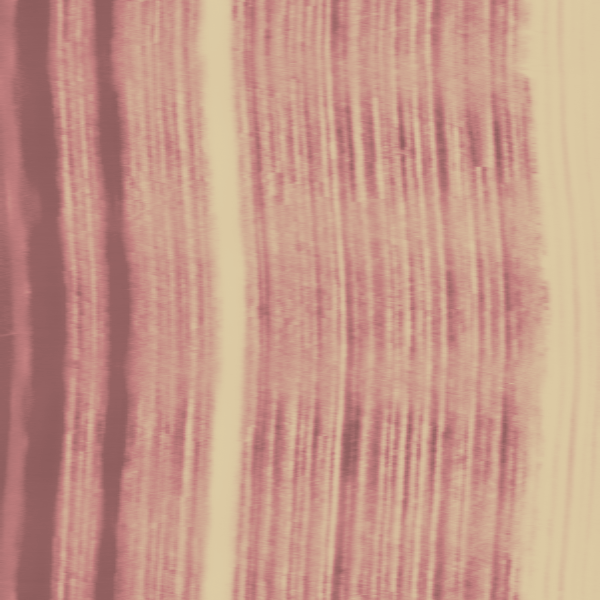

## 1. Approach & Methodology

We lived by the quote "a journey of a thousand miles begins with a single step." Our approach was slow, but calculated. Each section follows the approach that was taken in that specific task. We also believe in **repository automation** and **reproducible research**. All scripts should be easy to use, requiring a simple 'Run' at most. Functions should also be as easy as possible to understand, with notes, usage, and explanations provided within each function's file. 

### 1.1 Defining the Defects

The first step to any image defect detection system is defining the defects. Defect images in this dataset deviate from the natural, vertical graininess of the wood. These defective wood grain images are all categorized in one defect folder (test/ko). However, for clarity and documentation, our team has split the defects further into three distinct categories. The three categories are important in understanding our batch testing results:

#### Scratch Defect

A **scratch defect** is a physical surface flaw in the wood grain. They present as a **thin, elongated cut/scrape** into the wood surface. Scratches are **darker than the wood** surrounding them and they **run against the vertical grain, being inherently horizontal**. Scratches in the image are also a localized anomaly, meaning multiple scratch marks tend to be clumped up in one part of the image, never covering the whole image. In terms of classical image processing, the texture, shape, and direction of this defect make it easy to isolate. They are the most common defect in this dataset, and one that most defect images carry:

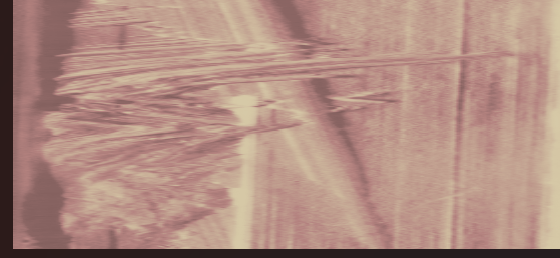

#### Brush Defect

A **brush defect** is a compact,** blob-shaped region **where the wood grain texture appears to be disrupted or covered over. These blobs present locally, replacing fine vertical grain pattern with a smoother, more uniform patch. A brush defect is comprised of two regions: a boundary and an interior. The **boundary of a brush defect conflicts with vertical grain, **while the interior is too smooth for directional filters to measure. In terms of classical image processing, this makes the brush defect are harder to isolate, as their boundary and interiors share different properties. The interior being lighter color than the boundary makes a single defect isolation tool useless in capturing both, necessitating the use of multiple methods being employed simultaneously (FFT & Entropy Filter). 

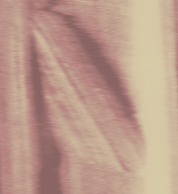

#### Super-Fine Scratch Defect

A super-fine scratch is the smallest defects in the dataset, yet make up 54% of defect images in the dataset. It presents as a **thin, elongated cut/scrape** into the wood surface, with a small caveat. **Super-fine scratches tend to only be a couple of pixels tall. **In terms of classical image processing, this scratch is deceptively difficult to isolate. Directional filters can detect these scratches, but the size of these defects makes them **EXTREMELY fragile to thresholding**. On the AI end, the small size of the defects combined with Resnet18's 224 × 224 pixels input make **the AI COMPLTELY ignore this defect.**

### 1.2 Classical Detection Systems 

The clear categorization of defects allowed us to effectively set the foundation for a couple of detection systems. Each classical detection system used in this script has been worked on and reworked countless times for the express purpose of competing with the AI classifier. In trying to outperform the AI classifier, the classical detection can be used as a fallback option when the AI fails, which was the case in Batch Testing (explored in Design Decisions & Tradeoffs). 

Inital testing included eyeballing the masks against the defect images and concept testing different image processing techniques. This methodology was used for the first couple drafts of scratch and brush detection as our team was new to the image processing tools. However, a more efficient and effective process soon took over.

The aimless nature of trying to match the mask to the defect in the image was frustrating to work with, which is where the detailed detect categorization, small-scale batch testing, and evidence metrics data collecting was employed. Defining the defects in great detail allow us to narrow in on specific techniques and choose useful metrics. With scratches, researching led us to the Frangi vesselness function. The batch testing provided us with a wealth of evidence data, which, when processed and clean-up, showed us that non-defect images has a significantly higher MeanAngleDeviation compared to defect images containing scratches. 

Through this method, our classical detection exceeded the 'minimal image processing' requirement of the original project, while overall being a more robust, standalone system. Each classical detection system is also equipped with notes on fixes, issues, and a debug function. However, one pressing issue with the classical detection systems is apparent lack of a super-fine scratch defect detector. This detail will be talked about in the "Remaining Challenges" section.

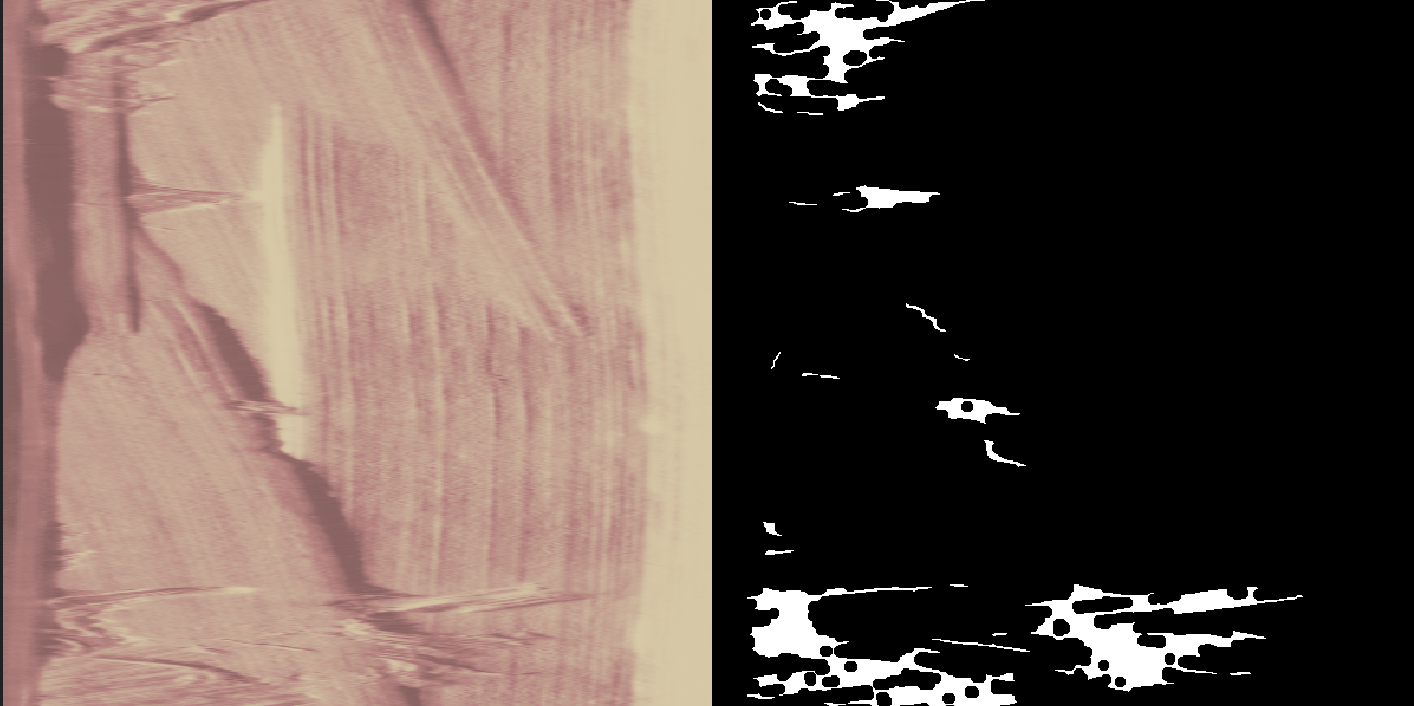

### 1.3 Hybrid Classification Architecture

Our hybrid architecture includes the classical evidence extraction (scratch/brush detectors) + transfer-learned ResNet-18 classifier + rule-based baseline, combined in `inspectPart.m`. AI gives the primary PASS/FAIL decision with confidence; classical evidence gives traceability, interpretability, and a sanity-check baseline, with the ability to override the AI in chosen situations. This is a required function for this project and the function that was put through the final batch test. 

### 1.4 Batch Testing Methodology

Beantech's datasets come pre-sorted as `"test/" `and` "train/"`. Our batch testing was run locally, using the full `"test/"` dataset. This was done to create reproducibility without redistribution, reduce runtime on this current live script, and prevent excess consumption of user's storage space. The batch testing further runs on a two-tier results system. The baseline results analyze the whole defect batch (test/). However, since our classical detection doesn't track super-fine scratches and the limitations of resnet18 cause the AI to completely miss them too, a second batch test, "`--- Fine Scratches Excluded -- PRIMARY RESULT ---" `is the set that our detection system was designed for. Super-fine scratches being incorrectly passed by our AI classifier with high confidence can be shown in the live demonstration's images 19 & 20, which is why the second dataset excluding them is necessary. 

## 2. Results & Analysis (Deliverables)

In-depth analysis of the results of our project all appear in this section. The full dataset batch testing produced two results: metrics for the datasets with all defects and metrics for the dataset excluding super-fine scratches. There is also a live, per-image demo of 

### 2.1 Baseline: Batch Testing with All Defects Included

For the sake of transparency, this first, failure batch result displays how the detection pipelines works on the whole testing dataset. The testing dataset includes 200 defective images and 30 clean images. Of all 230 images, the system's final decision matched the true label 53.48% of the time. Only being correct half the time is terrible for an inspection system. An actual yield of 13.04% means that only a few of the images (30/230) were actually clean images, yet our system's predicted yield was passing nearly 60% of the images as clean. However, there was a silver lining.

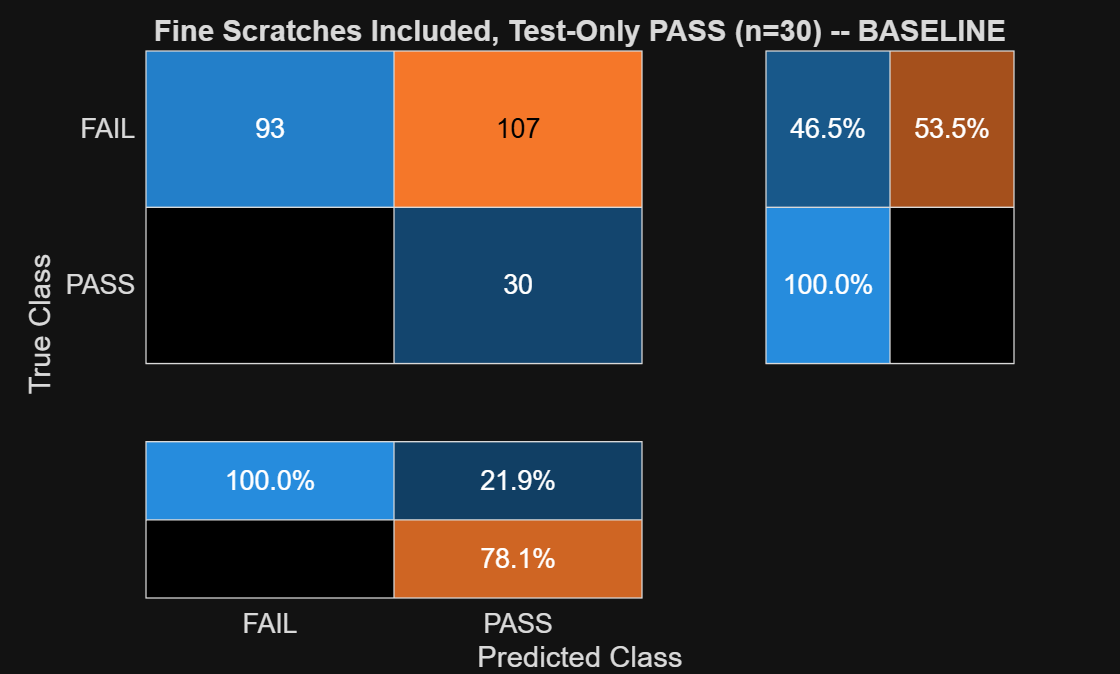

=== Fine Scratches Included, Test-Only PASS (n=30) -- BASELINE ===


Generated:          29-Jul-2026 22:14:27


PASS source:        test/ok only (n=30, no leakage)


Test set size:       230


Accuracy:            53.48%


Actual yield:        13.04%


Predicted yield:     59.57%


Defect rate:         40.43%


False reject rate:   0.00%


False accept rate:   53.50%


AI/rule disagreement rate: 6.96%


%% BASELINE RESULT (All defects)
% This is one of two precomputed full-dataset result files committed to
baselineLabel = "Fine Scratches Included, Test-Only PASS (n=30) -- BASELINE";
baselineFile  = fullfile(imageSampleSetsDir, "fullDatasetResults_test30.mat");

if ~isfile(baselineFile)
    warning("batchTestRunner:missingResultFile", ...
        "%s not found.\n", baselineFile);
else
    B = load(baselineFile, "fullResults");
    frBaseline = B.fullResults;

    figure("Name", baselineLabel);
    cmBaseline = confusionchart(frBaseline.confMat, frBaseline.classNames);
    cmBaseline.Title = baselineLabel;
    cmBaseline.RowSummary = "row-normalized";
    cmBaseline.ColumnSummary = "column-normalized";

    fprintf("=== %s ===\n", baselineLabel);
    fprintf("Generated:          %s\n", string(frBaseline.dateGenerated));
    if isfield(frBaseline, "passSource")
        fprintf("PASS source:        %s\n", frBaseline.passSource);
    end
    fprintf("Test set size:       %d\n", frBaseline.numTest);
    fprintf("Accuracy:            %.2f%%\n", frBaseline.accuracy * 100);
    fprintf("Actual yield:        %.2f%%\n", frBaseline.yieldActual * 100);
    fprintf("Predicted yield:     %.2f%%\n", frBaseline.yieldPredicted * 100);
    fprintf("Defect rate:         %.2f%%\n", frBaseline.defectRate * 100);
    fprintf("False reject rate:   %.2f%%\n", frBaseline.falseRejectRate * 100);
    fprintf("False accept rate:   %.2f%%\n", frBaseline.falseAcceptRate * 100);
    fprintf("AI/rule disagreement rate: %.2f%%\n", frBaseline.disagreementRate * 100);
end

While it would have been easy to mark this run as an absolute failure, there were a few key distinctions that made our team rethink the results. A false reject rate of 0% means that all clean images were being passed correctly, making the clean images a non-issue. This naturally means that the defects are the issue. This is supported by the fact that the false accept rate is 53.50%, meaning nearly half of defects are being counted as passing. Furthermore, the AI disagreement rate was a low 7%, indicating that both the classical and AI were being fooled by nearly half the defects in the dataset. Taken all together, a hypothesis was born. This systemic issue is a consequence of the super-fine scratch defect. This is where the second batch test was created.

### 2.2 Refined: Batch Testing Excluding Super-fine Scratch Defect

This second batch excludes the last 120 defects, which completely eliminates super-fine scratches (along with 12 other defects). This change causes the accuracy jumps from 53.48% to 100%, nearly doubling. This accuracy is evident in the false acceptance rate going from 53.5% all the way down to 0%, indicating that defects are no longer passing through the system undetected. Since super-fine scratches account for 54% (108/200) of all defects and all 107 defects that falsely passed the baseline no longer pass, this implies that all the 107 false acceptances were part of the 108 super-fine scratch defects, with only 1 super-fine defect actually being detected in both batches (image 107, shown in Live Demo Image 20). 

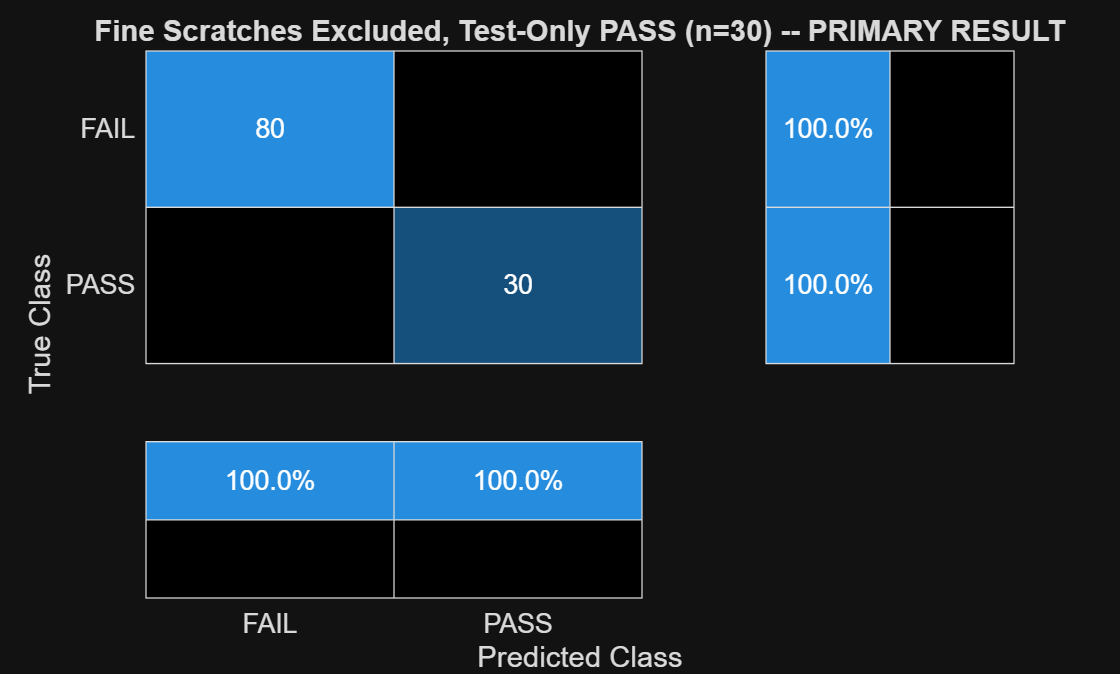


=== Fine Scratches Excluded, Test-Only PASS (n=30) -- PRIMARY RESULT ===


Generated:          29-Jul-2026 22:08:34


PASS source:        test/ok only (n=30, no leakage)


Test set size:       110


Accuracy:            100.00%


Actual yield:        27.27%


Predicted yield:     27.27%


Defect rate:         72.73%


False reject rate:   0.00%


False accept rate:   0.00%


AI/rule disagreement rate: 4.55%


%% Final Results
% Same PASS set (test/ok, n=30), same defect source (test/ko), with the ONLY
% difference being fine-scratch defects (idx >= 80) are excluded. This
% isolates fine scratches' effect on accuracy/FAR since every other
% variable is held constant. 
primaryLabel = "Fine Scratches Excluded, Test-Only PASS (n=30) -- PRIMARY RESULT";
primaryFile  = fullfile(imageSampleSetsDir, "fullDatasetResults_noFineScratch_test30.mat");

if ~isfile(primaryFile)
    warning("batchTestRunner:missingResultFile", ...
        "%s not found.\n", primaryFile);
else
    P = load(primaryFile, "fullResults");
    frPrimary = P.fullResults;

    figure("Name", primaryLabel);
    cmPrimary = confusionchart(frPrimary.confMat, frPrimary.classNames);
    cmPrimary.Title = primaryLabel;
    cmPrimary.RowSummary = "row-normalized";
    cmPrimary.ColumnSummary = "column-normalized";

    fprintf("\n=== %s ===\n", primaryLabel);
    fprintf("Generated:          %s\n", string(frPrimary.dateGenerated));
    if isfield(frPrimary, "passSource")
        fprintf("PASS source:        %s\n", frPrimary.passSource);
    end
    fprintf("Test set size:       %d\n", frPrimary.numTest);
    fprintf("Accuracy:            %.2f%%\n", frPrimary.accuracy * 100);
    fprintf("Actual yield:        %.2f%%\n", frPrimary.yieldActual * 100);
    fprintf("Predicted yield:     %.2f%%\n", frPrimary.yieldPredicted * 100);
    fprintf("Defect rate:         %.2f%%\n", frPrimary.defectRate * 100);
    fprintf("False reject rate:   %.2f%%\n", frPrimary.falseRejectRate * 100);
    fprintf("False accept rate:   %.2f%%\n", frPrimary.falseAcceptRate * 100);
    fprintf("AI/rule disagreement rate: %.2f%%\n", frPrimary.disagreementRate * 100);
end

This result signifies that both the AI and the classical detection are both missing these super-fine, tiny defects. This is not for a lack of trying however, as will be shown in Design Decision & Tradeoffs.

### 2.3 Live Demonstration

This live demo is a small display of `inspectPart.m `in action. A small batch of images can be selected with the slider and this script will report detailed per-image stats. The first 10 images are clean images from the training set, while images 11-20 are defect images. 

%% The Live Demo

if ~isfolder(sampleDataFolder)
    warning("batchTestRunner:noSampleImages", ...
        "%s not found. Skipping Part B (live demo).", sampleDataFolder);
    return;
end

% Download the trained net from GitHub Releases if it isn't already here
if ~isfile(netMatFile)
    fprintf("Trained network not found locally. Downloading from GitHub Releases...\n");
    fprintf("  %s\n", netReleaseURL);
    try
        websave(netMatFile, netReleaseURL);
        fprintf("Download complete: %s\n", netMatFile);
    catch ME
        if isfile(netMatFile)
            delete(netMatFile);
        end
        error("batchTestRunner:downloadFailed", ...
            "Could not download the trained network from:\n  %s\nError: %s\n" + ...
            "Check that netReleaseURL above is correct, or manually download " + ...
            "%s from the repo's Releases page and place it in %s.", ...
            netReleaseURL, ME.message, netFileName, repoDir);
    end
end

S = load(netMatFile);
net           = S.netTransfer;
netClassNames = S.classNames;

imdsSample = imageDatastore(sampleDataFolder);   % flat images/ folder, no subfolders
numSample = numel(imdsSample.Files);

% True labels come from filename PREFIX ("clean_" / "defect_"), not
% folder names -- sample_test_02/images/ has no subfolder structure.
trueLabelsAll = strings(numSample, 1);
for i = 1:numSample
    [~, name, ~] = fileparts(imdsSample.Files{i});
    if startsWith(name, "clean_", "IgnoreCase", true)
        trueLabelsAll(i) = "PASS";
    elseif startsWith(name, "defect_", "IgnoreCase", true)
        trueLabelsAll(i) = "FAIL";
    else
        warning("batchTestRunner:unrecognizedFilePrefix", ...
            "File '%s' doesn't start with 'clean_' or 'defect_' -- true label unknown, marking as FAIL by default. Check this filename.", name);
        trueLabelsAll(i) = "FAIL";
    end
end

%% ===================== INTERACTIVE IMAGE SELECTOR =========================
% Pick which sample image to inspect.
imageIndex = 1;

%% ===================== INSPECTION RESULT FOR SELECTED IMAGE ================
imageIndex = max(1, min(numSample, round(imageIndex)));   % clamp to valid range

I = readimage(imdsSample, imageIndex);
[~, thisName, thisExt] = fileparts(imdsSample.Files{imageIndex});
trueLabel = trueLabelsAll(imageIndex);

fprintf("\n=== Image %d of %d: %s%s (true label: %s) ===\n", ...
    imageIndex, numSample, thisName, thisExt, trueLabel);


=== Image 1 of 20: clean_0000.png (true label: PASS) ===


*** OVERRIDE: AI confidence 0.50 < 0.75 -- using rule-based decision ***
Final Decision:    FAIL
NOTE: flagged by brush only -- check for curved-grain false positive
=== Hybrid Inspection Result ===
AI Raw Decision:   FAIL (confidence 0.50)
Rule-Based Backup: FAIL (scratchFail=0, brushFail=1)


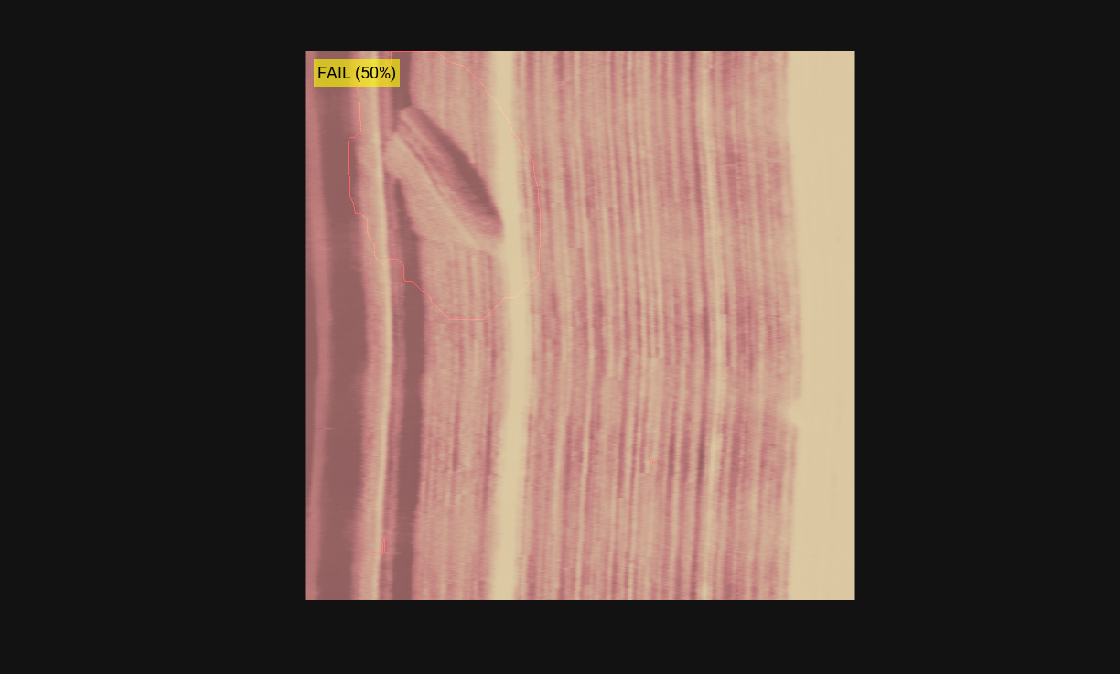


result = inspectPart(I, net, netClassNames, true);   % showDebug=true -> shows evidence overlay


isCorrect = strcmp(string(result.finalLabel), trueLabel);

fprintf("\n--- Full Stats for This Image ---\n");


--- Full Stats for This Image ---


fprintf("True label:              %s\n", trueLabel);

True label:              PASS


fprintf("Final decision:          %s   %s\n", result.finalLabel, ternary(isCorrect, "(CORRECT)", "(WRONG)"));

Final decision:          FAIL   (WRONG)


fprintf("AI raw decision:         %s (confidence %.2f)\n", result.aiRawLabel, result.confidenceScore);

AI raw decision:         FAIL (confidence 0.50)


fprintf("Confidence override:     %s\n", ternary(result.overrideApplied, "YES -- baseline used instead of AI", "no"));

Confidence override:     YES -- baseline used instead of AI


fprintf("Rule-based baseline:     %s\n", result.baselineDecision);

Rule-based baseline:     FAIL


fprintf("AI/baseline disagreement:%s\n", ternary(result.disagreementFlag, "YES", "no"));

AI/baseline disagreement:no


fprintf("Cross-detector agreement:%s\n", ternary(result.crossDetectorAgreement, "YES (scratch AND brush both flagged)", "no"));

Cross-detector agreement:no


fprintf("\nEvidence metrics:\n");


Evidence metrics:


evidenceFields = fieldnames(result.evidenceMetrics);
for f = 1:numel(evidenceFields)
    fprintf("  %-30s %.4f\n", evidenceFields{f}, result.evidenceMetrics.(evidenceFields{f}));
end

  scratch_NumRegions             3.0000
  scratch_TotalDefectPixels      159.0000
  scratch_LargestRegionArea      78.0000
  scratch_PercentageFlagged      0.0442
  scratch_MaxAspectRatio         7.0125
  scratch_MaxAngleDeviation      47.7079
  scratch_MeanAngleDeviation     41.8834
  scratch_IntensityContrast      0.8454
  brush_NumRegions               1.0000
  brush_TotalDefectPixels        45458.0000
  brush_LargestRegionArea        45458.0000
  brush_PercentageFlagged        12.6272
  brush_AvgSolidity              0.9614
  brush_TextureDeficit           -0.0264
  brush_IntensityContrast        0.0197
  combined_PercentageFlagged     12.6497



function out = ternary(cond, a, b)
if cond, out = a; else, out = b; end
end

### 2.4 Segment Defect Vs Classical Detection

There is a separate live script for this titled `segmentDefectDemo.mlx`. Segment defect live script is independent from the detection pipelines and showcases s`egmentDefect.m (`the optional deliverable). A classical detection function was prepared for every dataset to allow you to compare segmentDefect's accuracy across all three datasets!

## 3. Design Decisions & Tradeoffs

### 3.1 Confidence-Gated Override 

### 3.2 Scratch Detection Threshold

### 3.3 Removed finescratchDetection.m

### 3.4 brushDetection.m's Cross Grain Sensitivity

### 3.5 Teammates Lack of Communication

## 4. Remaining Challenges

This section will cover issues unaddressed due to time constrains that reduce the effectiveness of this detection pipeline. If this were a larger scale project, these would be the places to look for refinenment.

### The resnet18 224×224 input resizing 

### Ground Truth's Lies

### Brush Detection Anomaly 

### 12 unaccounted images in final batch test

5. Conclusion